## Ligninger

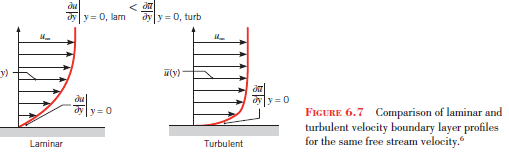

## Opgaver

## Opgave 6.33

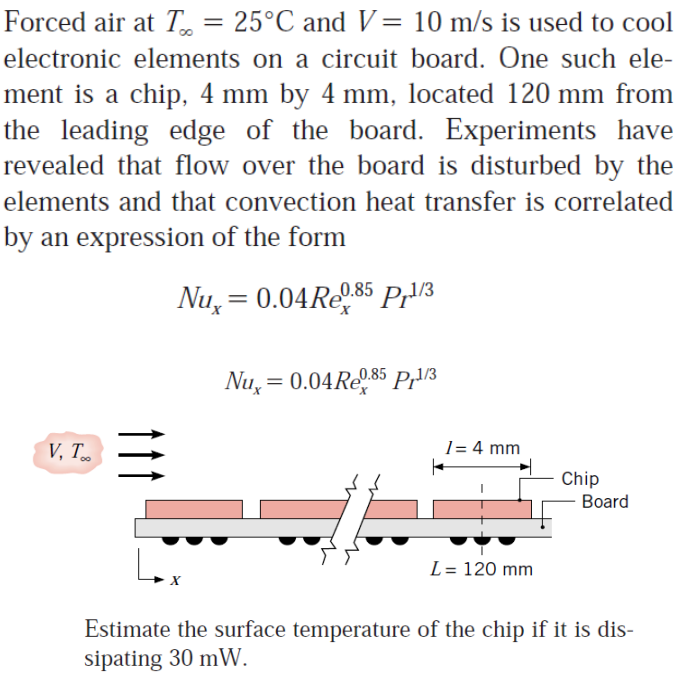

clear all
fluid = 'Air'

T_inf = 299

CoolProp = py.importlib.import_module('CoolProp.CoolProp');

q = 0.0300

P = 101325; % Pascal eller 1e5 %surface pressure
T_inf = 25 +273.15; %K

c_p = CoolProp.PropsSI('Cpmass', 'P', P, 'T', T_inf, fluid) %specificHeat_p
k = CoolProp.PropsSI('conductivity', 'P', P, 'T', T_inf, fluid) %thermalConductivity
mu = CoolProp.PropsSI('viscosity', 'P', P, 'T', T_inf, fluid) %Dynamisk viscositet
rho = CoolProp.PropsSI('D', 'P', P, 'T', T_inf, fluid); %Densitet
V = 10; %m/s
l = 4e-3; %m

Ts = 316.5000

L = 0.120; %m
% mu = 1.84e-5; % kg/(m·s) eller N⋅s/m2

Tf = 307.7500

q = 30e-3; % W

L = 0.0040

A = 1.6000e-05

V = 10

l = 0.1200

% c_p = 1007; %J/kg⋅K
% k = 26.3e-3; %W/m⋅K varme conductivitet

v = 1.6690e-05

A = l * l

k = 0.0269

nu = mu/rho %kinematisk viskositet %1.5577e-5; 

Pr = 0.7030


Re_x = V*L/nu
Pr = c_p * mu / k

Re_x = 7.1899e+04


Nu_x = 0.04*Re_x^(0.85) * Pr^(1/3)

Nu_x = 477.8166


h = Nu_x/L * k
% R_tot = 1/(h*A)

$$h\_strej = 107.11056411190246734577158349566$$


syms T_sym
T = solve(q == (T_sym - T_inf) * h*A, T_sym);
vpa(T - 273.5, 5)

$$T = 316.50527611861997487715042871686$$


q/(A*h) + 25

$$ans = 42.505276118619974877150428716861$$

clear all
T_inf = 25 + 274
q = 30/1000

L = 0.004
A = L^2
V = 10
l = 0.12


%Gæt på Ts
Ts = 45 + 274
%tf for at finde materiale værdiger her er det smart at bruge coolprop! 
Tf = (Ts + T_inf) / 2

%Tabel værdiger 
v = 16.69E-6 
k = 26.9E-3 
Pr = 0.703

%Vi kan finde nussels tal til at finde h for newtons kølings lov.
Re_x = (V*l)/v

Nu_x = 0.04*Re_x^(0.85)*Pr^(1/3)

syms h
h_strej = vpa(solve(Nu_x == (h*l)/k, h))

%så kan vi bruge newtons kølings lov
syms T
T = solve(q == h_strej*A*(T - T_inf), T)

T - 274



## Figurer og tabeller